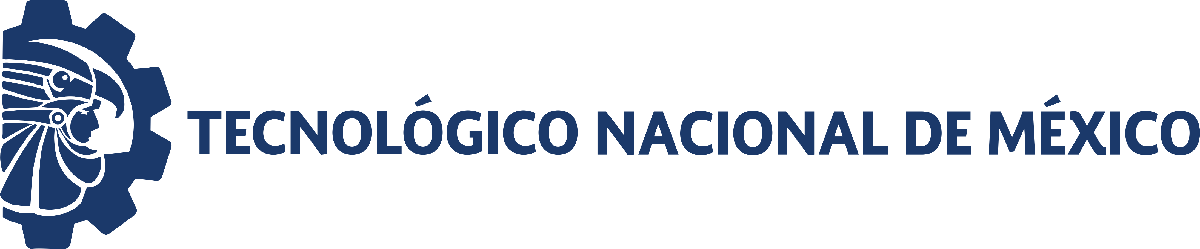                                 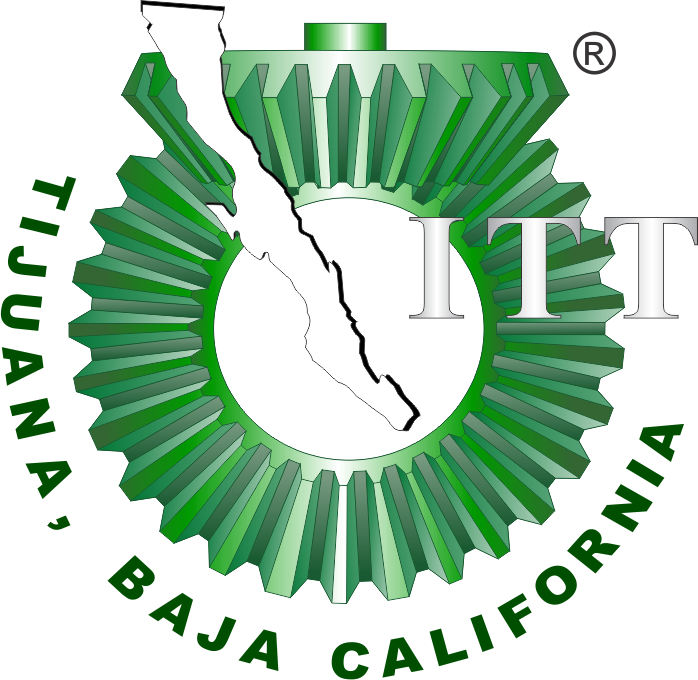

# Práctica tres: Sistema Muscoloesqueletico  

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

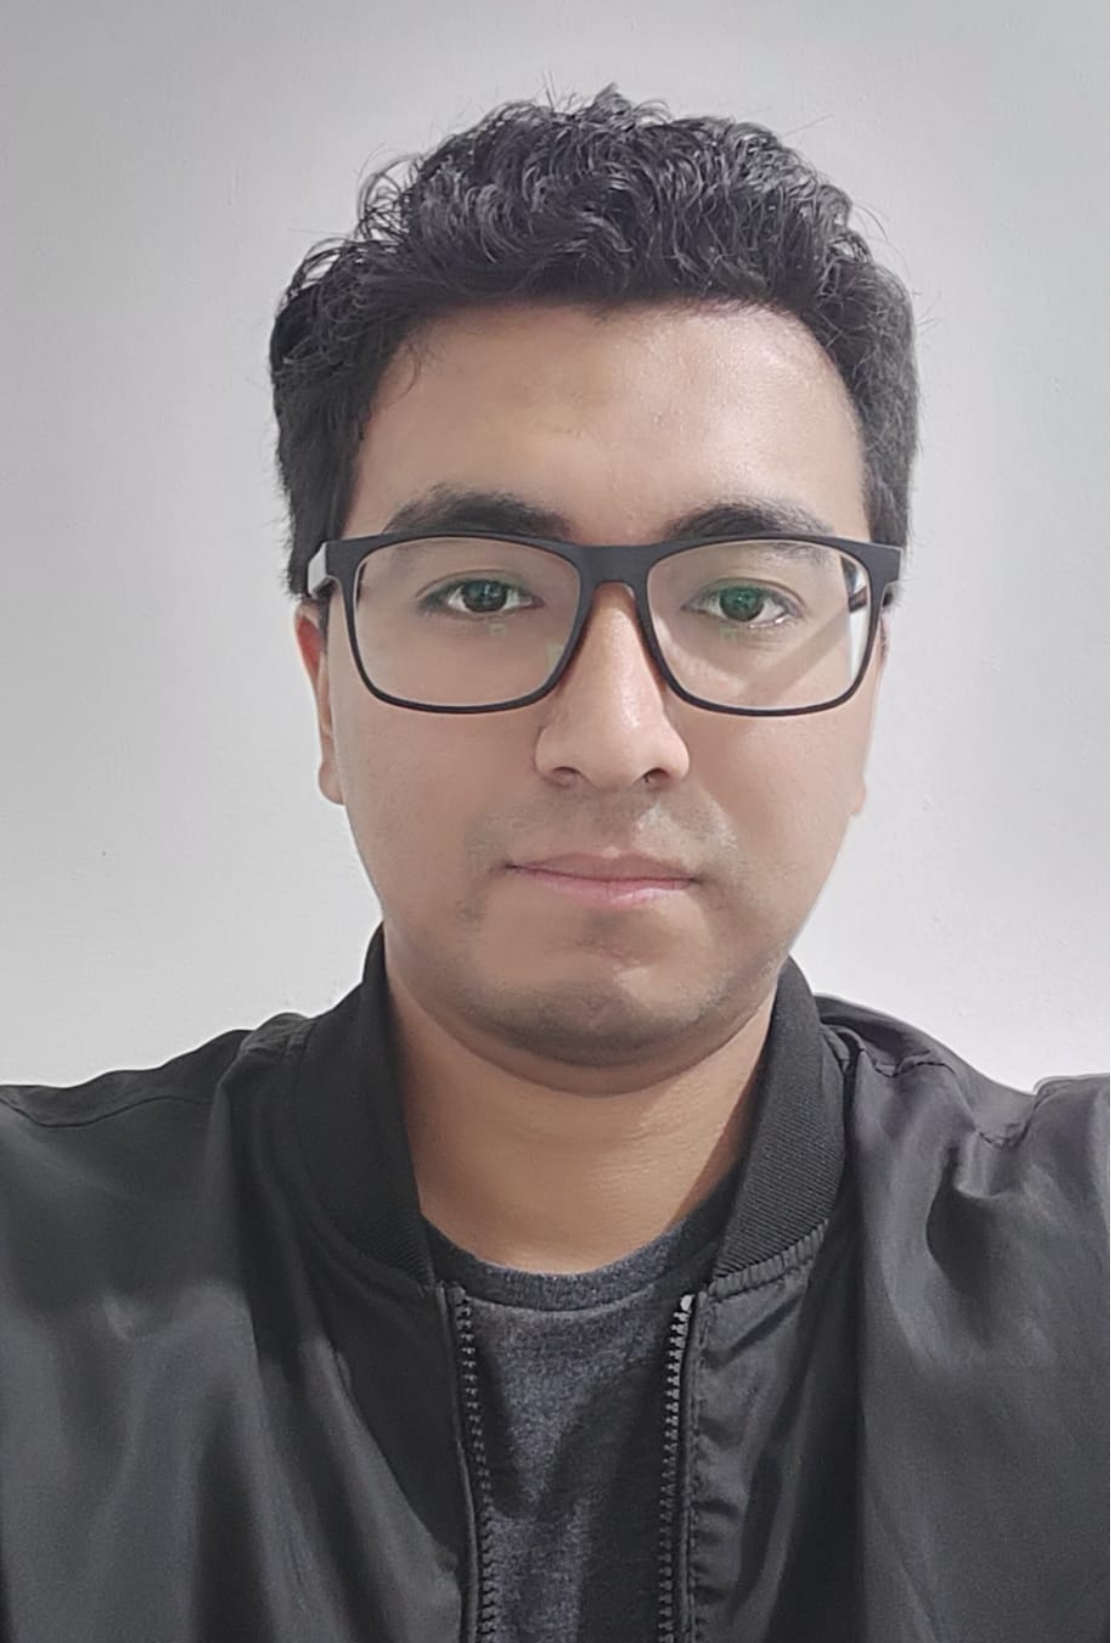

Nombre del alumno: Carlos Daniel Frausto Luna

Número de control: C18210366

Correo institucional: LC18210366**@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %tiempo de la simulacion en dias 
dt = 1E-3; %Intervalo de integracion para el metodo de la solucion oir diferencias finitas 
n = round(tend/dt); %Cantidad de interaciones para el metodo numerico 

%Condiciones iniciales base para cada paciente 
x1_0 = 59;x2_0 = 44; x3_0 = 885;
%Parametros particulaes para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
 beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed= 18210366; %semilla para asegurar reproducibilidad 
rng(seed,'twister')

%intrvalo de las condiciones iniciales 
xmin= 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0)=');(x1_0')

x1(0)=


ans =    58.4716   59.4256   58.8274   59.5532   58.8725   58.6282   59.4151   58.8962   59.1421   59.0377


x2_0 = x2_0*interval; disp('x2(0)=');(x2_0')

x2(0)=


ans =    43.6059   44.3174   43.8713   44.4126   43.9049   43.7227   44.3095   43.9226   44.1060   44.0281


x3_0 = x3_0*interval; disp('x3(0)=');(x3_0')

x3(0)=


ans =   877.0740  891.3843  882.4113  893.2980  883.0873  879.4233  891.2262  883.4437  887.1317  885.5655


;

## Caso: sin transfuncion sanguinea [u(t)=0]

u = zeros(n+1,1); %No hay transfucion 
fig = 1;
for i=1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Transfuncion sanguinea [u(t)=1 [t1,t2]]

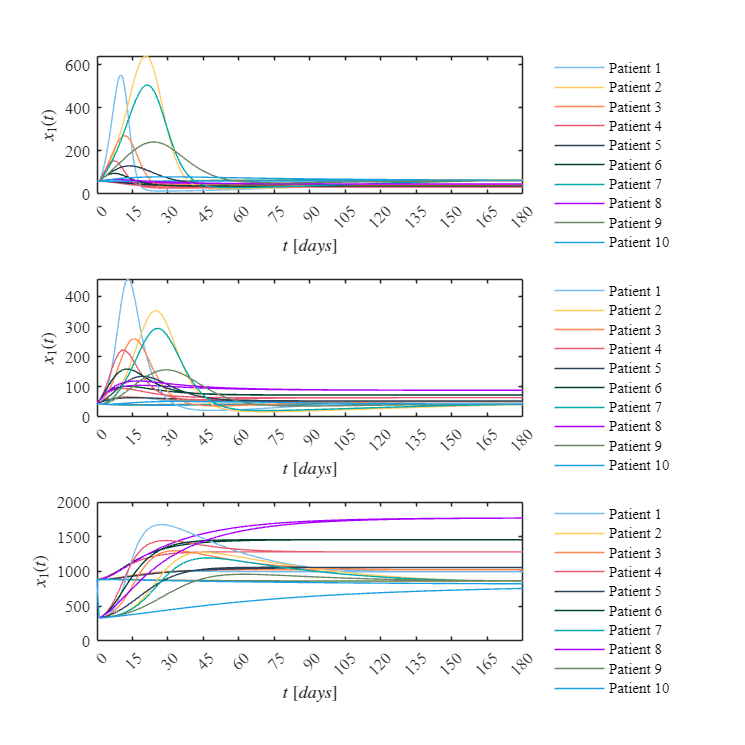

u2 = zeros(n+1,1); u2(1:1000)= 1; %Hay transfucion 
fig = 2;
for i=1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u2,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funcion: modelo matematico 


$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_4 } =\beta \left(k_2 x_2 -k_3 x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system (x1_0,x2_0,x3_0,beta,gamma,u,dt,tend);
    %parametros fijos del sistema 
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t =(0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;

    for i= 1:n
        x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i))+gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i))-u(i)*x3(i))*dt;

    end
end

## Funcion: soluciones en el tiempo 

function plotdata (t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,20,20])
    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;
                0,171,169;
                170,0,255;
                109,135,100;
                27,161,226;]/255;
    colororder(mycolors)

    subplot (3,1,1)
    hold on; grid off, box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend ('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5', ...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot (3,1,2)
    hold on; grid off, box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend ('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5', ...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    
    subplot (3,1,3)
    hold on; grid off, box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend ('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    if fig ==1 
        exportgraphics(gcf,'Caso sin transfucion.pdf', 'ContentType','vector')
        exportgraphics(gcf,'Caso sin transfucion.png', 'ContentType','vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso con transfucion.pdf', 'ContentType','vector')
        exportgraphics(gcf,'Caso con transfucion.png', 'ContentType','vector')
    end
end